# 弹簧振子状态空间模型

## 准备工作

将后续需要的部分变量进行定义

clc;clear;close all; % 清屏，清除工作区变量，关闭所有图窗
tspan = [0 10]; % 设置开始和结束时间
X0 = [0.5; 0; 0.25; 0; 0.1; 0]; % 设定状态变量初值，列向量
[k1,k2,k3,k4] = deal(10);   % 定义弹簧弹性系数k1~k4
[m1 ,m2, m3] = deal(1);     % 定义滑块质量m1~m3
% zeta = -0.05;
IND = [0 1 0 0 0 0;           % 构造系统矩阵A
    -(k1+k2)/m1 0 k2/m1 0 0 0; 0 0 0 1 0 0; 
    k2/m2 0 -(k2+k3)/m2 0 k3/m2 0;
    0 0 0 0 0 1;
    0 0 k3/m3 0 -(k3+k4)/m3 0];

## 使用ode45函数解状态方程


$$% MathType!MTEF!2!1!+-
% feaahqart1ev3aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBaerbd9wDYLwzYbItLDharqqtubsr
% 4rNCHbWexLMBbXgBd9gzLbvyNv2CaeHbl7mZLdGeaGqiVu0Je9sqqr
% pepC0xbbL8F4rqqrFfpeea0xe9Lq-Jc9vqaqpepm0xbba9pwe9Q8fs
% 0-yqaqpepae9pg0FirpepeKkFr0xfr-xfr-xb9adbaqaaeGaciGaai
% aabeqaamaabaabauaakeaadaWadaqaauaabeqageaaaaqaaiqadIha
% gaGaamaaBaaaleaacaaIXaGaaGymaaqabaaakeaaceWG4bGbaiaada
% WgaaWcbaGaaGymaiaaikdaaeqaaaGcbaGabmiEayaacaWaaSbaaSqa
% aiaaikdacaaIXaaabeaaaOqaaiqadIhagaGaamaaBaaaleaacaaIYa
% GaaGOmaaqabaaakeaaceWG4bGbaiaadaWgaaWcbaGaaG4maiaaigda
% aeqaaaGcbaGabmiEayaacaWaaSbaaSqaaiaaiodacaaIYaaabeaaaa
% aakiaawUfacaGLDbaacaqG9aWaamWaaeaafaqabeGbgaaaaaqaaiaa
% icdaaeaacaaIXaaabaGaaGimaaqaaiaaicdaaeaacaaIWaaabaGaaG
% imaaqaaiabgkHiTmaalaaabaGaam4AamaaBaaaleaacaaIXaaabeaa
% kiabgUcaRiaadUgadaWgaaWcbaGaaGOmaaqabaaakeaacaWGTbWaaS
% baaSqaaiaaigdaaeqaaaaaaOqaaiaaicdaaeaadaWcaaqaaiaadUga
% daWgaaWcbaGaaGOmaaqabaaakeaacaWGTbWaaSbaaSqaaiaaigdaae
% qaaaaaaOqaaiaaicdaaeaacaaIWaaabaGaaGimaaqaaiaaicdaaeaa
% caaIWaaabaGaaGimaaqaaiaaigdaaeaacaaIWaaabaGaaGimaaqaam
% aalaaabaGaam4AamaaBaaaleaacaaIYaaabeaaaOqaaiaad2gadaWg
% aaWcbaGaaGOmaaqabaaaaaGcbaGaaGimaaqaaiabgkHiTmaalaaaba
% Gaam4AamaaBaaaleaacaaIYaaabeaakiabgUcaRiaadUgadaWgaaWc
% baGaaG4maaqabaaakeaacaWGTbWaaSbaaSqaaiaaikdaaeqaaaaaaO
% qaaiaaicdaaeaadaWcaaqaaiaadUgadaWgaaWcbaGaaG4maaqabaaa
% keaacaWGTbWaaSbaaSqaaiaaikdaaeqaaaaaaOqaaiaaicdaaeaaca
% aIWaaabaGaaGimaaqaaiaaicdaaeaacaaIWaaabaGaaGimaaqaaiaa
% igdaaeaacaaIWaaabaGaaGimaaqaamaalaaabaGaam4AamaaBaaale
% aacaaIZaaabeaaaOqaaiaad2gadaWgaaWcbaGaaG4maaqabaaaaaGc
% baGaaGimaaqaaiabgkHiTmaalaaabaGaam4AamaaBaaaleaacaaIZa
% aabeaakiabgUcaRiaadUgadaWgaaWcbaGaaGinaaqabaaakeaacaWG
% TbWaaSbaaSqaaiaaiodaaeqaaaaaaOqaaiaaicdaaaaacaGLBbGaay
% zxaaWaamWaaeaafaqabeGbbaaaaeaacaWG4bWaaSbaaSqaaiaaigda
% aeqaaaGcbaGaamiEamaaBaaaleaacaaIYaaabeaaaOqaaiaadIhada
% WgaaWcbaGaaG4maaqabaaakeaacaWG4bWaaSbaaSqaaiaaisdaaeqa
% aaGcbaGaamiEamaaBaaaleaacaaI1aaabeaaaOqaaiaadIhadaWgaa
% WcbaGaaGOnaaqabaaaaaGccaGLBbGaayzxaaaaaa!9CF5!
\[\left[ {\begin{array}{*{20}{c}}
{{{\dot x}_{11}}}\\
{{{\dot x}_{12}}}\\
{{{\dot x}_{21}}}\\
{{{\dot x}_{22}}}\\
{{{\dot x}_{31}}}\\
{{{\dot x}_{32}}}
\end{array}} \right]{\rm{ = }}\left[ {\begin{array}{*{20}{c}}
0&1&0&0&0&0\\
{ - \frac{{{k_1} + {k_2}}}{{{m_1}}}}&0&{\frac{{{k_2}}}{{{m_1}}}}&0&0&0\\
0&0&0&1&0&0\\
{\frac{{{k_2}}}{{{m_2}}}}&0&{ - \frac{{{k_2} + {k_3}}}{{{m_2}}}}&0&{\frac{{{k_3}}}{{{m_2}}}}&0\\
0&0&0&0&0&1\\
0&0&{\frac{{{k_3}}}{{{m_3}}}}&0&{ - \frac{{{k_3} + {k_4}}}{{{m_3}}}}&0
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{{x_1}}\\
{{x_2}}\\
{{x_3}}\\
{{x_4}}\\
{{x_5}}\\
{{x_6}}
\end{array}} \right]\]$$


ss_equation = @(t,X) IND*X;   % 构造匿名函数
[t,X] = ode45(ss_equation,tspan,X0);    % 使用ode45函数解常微分方程（状态方程形式的微分方程）

## 构造弹簧振子模型

### 计算正方形数据（中心点，连接点坐标，边界）

displacement = [X(:,1) X(:,3) X(:,5)];  % 获取三个滑块的位移量
F(length(displacement)) = struct('cdata',[],'colormap',[]); % 预分配一个数组frame以存储影片帧
RGB{length(displacement)} = 0;   % 预分配一个元胞数组im以存frame转成的image
x0 = 0; x1 = 4; % 定义横坐标范围
a = 0.3;    % a是正方形对角线/2的长度

x_center = [1 2 3] + displacement;  % 计算每个滑块中心点横坐标
y_center = 5;                       % 每个滑块中心点纵坐标均为5

theta = linspace(-3*pi/4,5*pi/4,5); % 矩阵角度范围
x_connection_points_left = x_center + a*cos(theta(1));  % 计算滑块左连接点坐标
x_connection_points_right = x_center + a*cos(theta(2)); % 计算滑块右连接点坐标

x_edge1 = a*cos(theta) + x_center(:,1); % 滑块1边界横坐标
x_edge2 = a*cos(theta) + x_center(:,2); % 滑块2边界横坐标
x_edge3 = a*cos(theta) + x_center(:,3); % 滑块3边界横坐标
y_square = a*sin(theta) + y_center; % 所有滑块边界纵坐标相同

### 计算弹簧数据

M = 20; % M是每段弹簧数据长度
x = [linspace(x0,x_connection_points_left(1,1),M); 
    linspace(x_connection_points_right(1,1),x_connection_points_left(1,2),M); 
    linspace(x_connection_points_right(1,2),x_connection_points_left(1,3),M);
    linspace(x_connection_points_right(1,3),x1,M)];
% 第一张图片弹簧横坐标
X = 4.9+mod(1:M,2)*0.2; % 第一张图片弹簧纵坐标
X(1:2) = 5; % 为弹簧头添加横线
X(end-1:end) = 5;   % 为弹簧尾添加横线

### 绘制初始图像

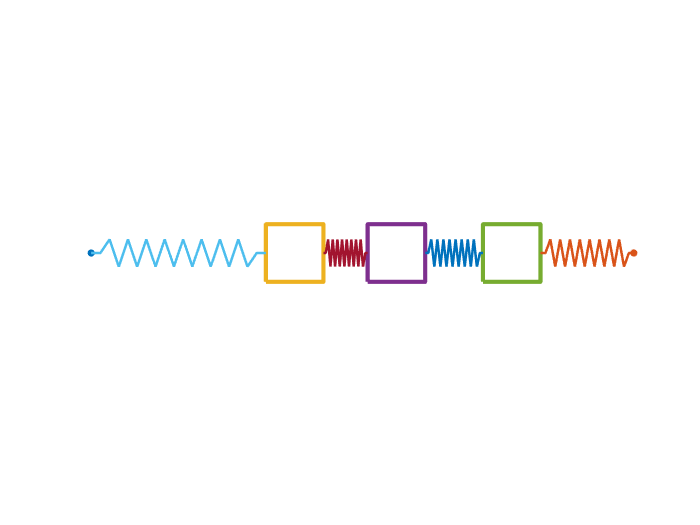

xlim([x0 x1]);  % 规定坐标轴横坐标范围
ylim([y_center-1 y_center+1]);  % 规定坐标轴纵坐标范围
axis equal  % 横纵坐标显示比例相同
axis off    % 隐藏坐标轴
hold on
p1 = plot(x0,y_center,'.',x1,y_center,'.',"MarkerSize",15);
p2 = plot(x_edge1(1,:),y_square,x_edge2(1,:),y_square,x_edge3(1,:),y_square,'LineWidth',2.5);
p3 = plot(x(1,:),X,x(2,:),X,x(3,:),X,x(4,:),X,'LineWidth',1.5);

### 绘制动画

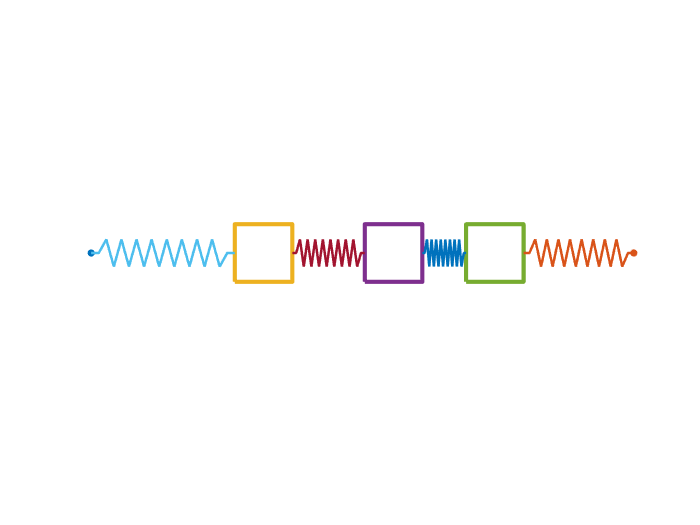

for i = 1:length(displacement)
    
    p2(1).XData = x_edge1(i,:); % 更新滑块1边界坐标
    p2(2).XData = x_edge2(i,:); % 更新滑块2边界坐标
    p2(3).XData = x_edge3(i,:); % 更新滑块3边界坐标
    p3(1).XData = linspace(x0,x_connection_points_left(i,1),M); % 更新第一段弹簧数据
    p3(2).XData = linspace(x_connection_points_right(i,1),x_connection_points_left(i,2),M); % 更新第二段弹簧数据
    p3(3).XData = linspace(x_connection_points_right(i,2),x_connection_points_left(i,3),M); % 更新第三段弹簧数据
    p3(4).XData = linspace(x_connection_points_right(i,3),x1,M);    % 更新第四段弹簧数据
    
    F(i) = getframe;    % 获取影片帧
    RGB{i} = frame2im(F(i)); % 转换为图片格式
end

## 播放视频

以50帧速率播放一遍，在实时脚本中无法实现

axis off
movie(F,1,50);  % 使用movie函数播放影片

## 将影片帧保存为动图gif

filename = 'test.gif';  % 定义文件名称
for i = 1:length(displacement)
    [IND,map] = rgb2ind(RGB{i},256);
    if i == 1
        imwrite(IND,map,filename,'gif',"LoopCount",Inf,"DelayTime",0);
    else
        imwrite(IND,map,filename,'gif',"WriteMode","append","DelayTime",0);
    end
end

**效果图如下**

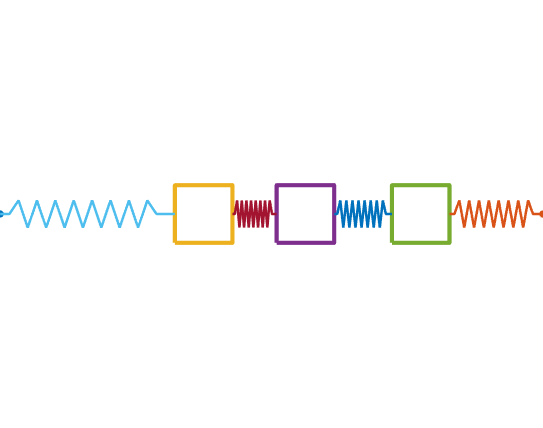

## 将影片帧保存为视频

默认是.avi格式，如果想转成.mp4格式，需要添加profile为MPEG-4，并且在编码过程中会自动将Height和Width填充为2的倍数，会显示大量警告信息

warning off % 添加warning off可忽略警告信息
% test = VideoWriter('test');
test = VideoWriter('test',"MPEG-4");
test.FrameRate = 30;    % 显示帧率
open(test)
writeVideo(test,F);
close(test)